## Exercice n°1 : Compensated Horner-Scheme

### Question n°1 : classic horner scheme implementation

format long
p = [1 2 3 4 5 6 7 8 9];
x = pi;
res1 = polyval(p,x)

res1 =      2.041366687877934e+04


res2 = Horner (p,x)

res2 =      2.041366687877934e+04


### Question n°2 and 3: EFT

Les fonctions sont disponibles en annexe 

res3 = CompHorner(p,x)

res3 =      2.041366687877935e+04


res4 = sHorner(p,x)

$$res4 = \frac{804339428848796563085155185914526542343166357819013704816272996470622804924749716302995921483121540830099911584013416609}{39402006196394479212279040100143613805079739270465446667948293404245721771497210611414266254884915640806627990306816}$$

### Question n°4 : Symbolic math

n = 3:42;
x = 1.333;
for i=1:length(n)
    a = poly(ones(1,n(i)));
    res1 = Horner    (a,x);     % Classic horner
    res2 = sHorner   (a,x);     % Thorical value
    res3 = CompHorner(a,x);     % Compensated Horner
    er1(i) = abs(res2-res1)/abs(res2);
    er2(i) = abs(res2-res3)/abs(res2);
    c(i) = condp(a,x);
    %c(i) = abs((x+1)/(x-1))^i;
    cond1(i) = 2*n(i)*eps*c(i);
    cond2(i) = eps + 4*n(i)*n(i)*eps*eps*c(i);
end

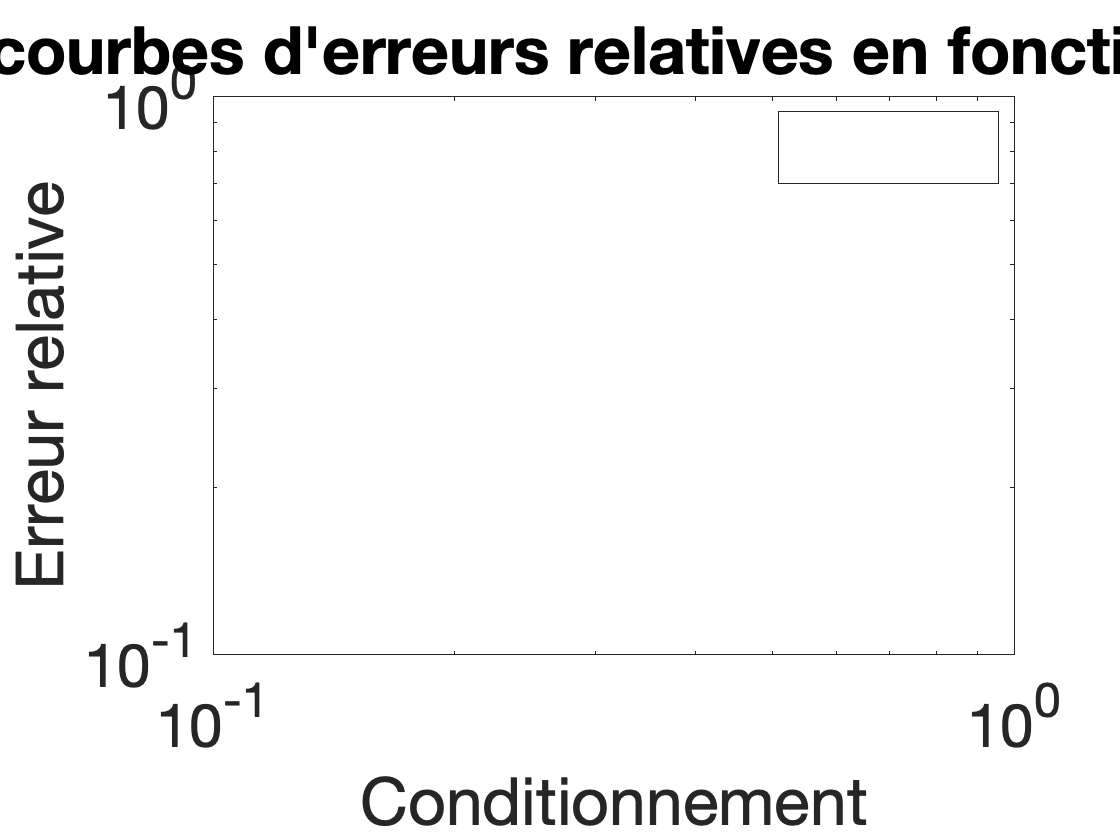

cla
axis tight

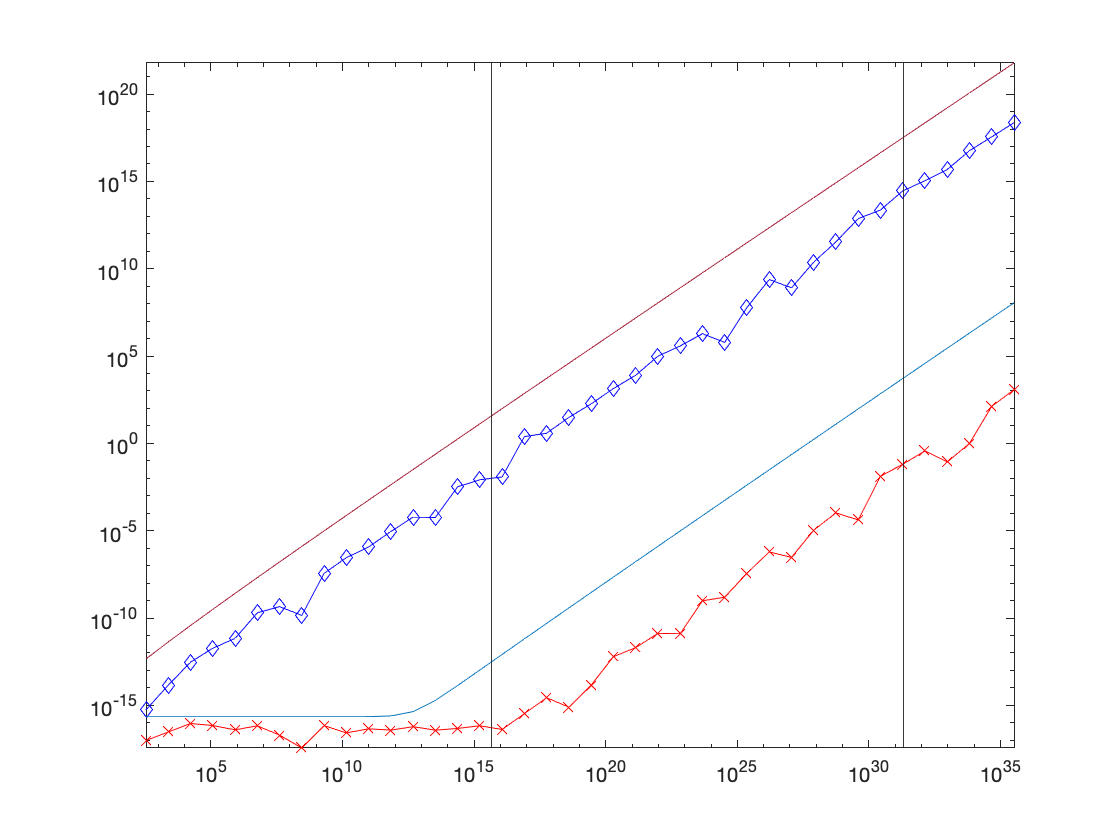

figure(1)
loglog(c,er1,'b--d')
hold on;
loglog(c,er2,'r--x')
%xlim([c(1) c(i)])
hold on
loglog(c,cond1)
hold on;
loglog(c,cond2)
hold on
xline(1/eps)
xline(1/(eps*eps))

n = 3:42;
for i=1:length(n)
   [p,C] = GenSum(n(i),c(i));
   Ci(i) = C;
   res5 = Sum(p);
   res6 = SCompSum(p);
   res7 = DCompSum(p);
   res8 = CompSum(p);
   exact = TSum(p);
   er5(i) = abs(exact-res5)/abs(exact);
   er6(i) = abs(exact-res6)/abs(exact);
   er7(i) = abs(exact-res7)/abs(exact);
   er8(i) = abs(exact-res8)/abs(exact);
   nu = (n(i)-1)*eps;
   gaman1 = nu/(1-nu);
   cond3(i) = gaman1*c(i);
   ScompCond(i) = 2*eps+eps*eps*n(i);
   DcompSumCond(i) = 2*eps;
   cond4(i) = eps + 4*n(i)*n(i)*eps*eps*c(i);
end

$$p = \left(\begin{array}{cccccc} -\frac{5654387917607597}{4611686018427387904} & \frac{5939199177333547}{17592186044416} & -\frac{5936534035641129}{17592186044416} & -\frac{816249366751}{10141204801825835211973625643008} & \frac{103063328440611}{9903520314283042199192993792} & \frac{252763074294389}{9903520314283042199192993792} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccc} -\frac{1222652888505815}{4503599627370496} & -\frac{720688664620223}{137438953472} & \frac{721391715330291}{137438953472} & -\frac{4951929088346501}{1125899906842624} & \frac{111059589393831}{5070602400912917605986812821504} & -\frac{599437028035}{2417851639229258349412352} & \frac{266294370397021}{1237940039285380274899124224} & -\frac{6173783118119}{39614081257132168796771975168} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccc} \frac{357452428786363}{137438953472} & \frac{7052551737256095}{144115188075855872} & \frac{5012830887094021}{2199023255552} & -\frac{2718376166021111}{549755813888} & \frac{2256411900955435}{35184372088832} & \frac{185521487946509}{1237940039285380274899124224} & \frac{29371168486389}{10141204801825835211973625643008} & \frac{495723429012281}{2475880078570760549798248448} & \frac{6987220029611}{19342813113834066795298816} & \frac{7893969445111}{1237940039285380274899124224} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccc} -\frac{4608942092094967}{8796093022208} & -\frac{1643015995091503}{36028797018963968} & \frac{4066128270532431}{1099511627776} & \frac{4837249815668521}{562949953421312} & -\frac{5995433656944159}{281474976710656} & -\frac{6953688328829225}{2199023255552} & -\frac{126452356975017}{2475880078570760549798248448} & -\frac{10818249317923}{20282409603651670423947251286016} & \frac{307988247337}{19342813113834066795298816} & \frac{790934884582339}{1267650600228229401496703205376} & -\frac{59381041040571}{79228162514264337593543950336} & -\frac{1856123059323989}{9903520314283042199192993792} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccc} \frac{8642090908556881}{18014398509481984} & -\frac{3574715364930041}{4398046511104} & \frac{1014773853784473}{70368744177664} & \frac{8264867924527509}{17179869184} & -\frac{8220343669691533}{17179869184} & \frac{8762867254029699}{36028797018963968} & -\frac{7889443704379337}{4398046511104} & \frac{7585686749393}{316912650057057350374175801344} & \frac{44372784979}{1208925819614629174706176} & \frac{52556433092737}{158456325028528675187087900672} & \frac{1129293907323}{75557863725914323419136} & \frac{2222561812001}{151115727451828646838272} & \frac{22419154898699}{10141204801825835211973625643008} & \frac{133567832965037}{1237940039285380274899124224} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccc} -\frac{1678705043472333}{281474976710656} & \frac{7361853493210483}{4398046511104} & \frac{6655595222995505}{536870912} & \frac{822315305878585}{8796093022208} & -\frac{1657547597154061}{134217728} & -\frac{6745974322169875}{137438953472} & \frac{891649899930245}{2251799813685248} & \frac{3255555212867443}{2251799813685248} & -\frac{436864689723759}{1267650600228229401496703205376} & -\frac{535263970855435}{9903520314283042199192993792} & -\frac{768701980163035}{1208925819614629174706176} & -\frac{352056736512293}{158456325028528675187087900672} & \frac{219578591692707}{302231454903657293676544} & \frac{270736075144613}{77371252455336267181195264} & -\frac{8115343592335}{316912650057057350374175801344} & \frac{10461608292807}{158456325028528675187087900672} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccc} \frac{7206930183823687}{562949953421312} & -\frac{8414127538365767}{1099511627776} & \frac{5154462344648315}{1099511627776} & -\frac{8160730979623549}{2199023255552} & -\frac{5657097586673585}{134217728} & -\frac{1288697408647527}{35184372088832} & \frac{554448632703927}{1073741824} & \frac{5588690671058255}{134217728} & \frac{8671463416420663}{18014398509481984} & \frac{44999187873603}{158456325028528675187087900672} & \frac{42663276076763}{1237940039285380274899124224} & -\frac{46415418040131}{154742504910672534362390528} & -\frac{3978399661}{1208925819614629174706176} & -\frac{16411911678379}{9444732965739290427392} & \frac{12195951355083}{9903520314283042199192993792} & -\frac{495847670958141}{19342813113834066795298816} & \frac{166527738886445}{302231454903657293676544} & \frac{39019195150291}{2535301200456458802993406410752} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccc} -\frac{432851198647283}{70368744177664} & -\frac{2816329530385903}{35184372088832} & -\frac{6265788410329409}{33554432} & -\frac{7007640429503603}{140737488355328} & -\frac{1133309647989}{2199023255552} & \frac{4253003302770553}{549755813888} & \frac{4734840305239933}{4398046511104} & \frac{2769717130899965}{67108864} & \frac{4880642767327955}{33554432} & -\frac{4232300141895507}{35184372088832} & \frac{125245315381313}{316912650057057350374175801344} & \frac{129720750944369}{19807040628566084398385987584} & \frac{125057974706279}{9444732965739290427392} & -\frac{7899813972889}{9903520314283042199192993792} & -\frac{11287324682901}{2535301200456458802993406410752} & -\frac{1678345961111}{19342813113834066795298816} & \frac{1190878399092167}{19807040628566084398385987584} & -\frac{14616713712103}{4722366482869645213696} & -\frac{21077473696207}{2361183241434822606848} & \frac{53558766518317}{9903520314283042199192993792} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccc} -\frac{8530210347462409}{1125899906842624} & -\frac{352801581755019}{2251799813685248} & \frac{7289415624043513}{1099511627776} & \frac{2458069951907383}{549755813888} & \frac{8444188530428831}{4194304} & -\frac{4222140084632375}{2097152} & \frac{6579610804760041}{281474976710656} & \frac{7964418554185351}{549755813888} & \frac{5460945793334523}{70368744177664} & -\frac{5954994865451975}{1099511627776} & \frac{6958244314441753}{4398046511104} & \frac{493707101092633}{1267650600228229401496703205376} & -\frac{8429456978889}{633825300114114700748351602688} & -\frac{17444553183559}{38685626227668133590597632} & \frac{21945188494197}{154742504910672534362390528} & -\frac{5816125255693}{590295810358705651712} & \frac{10834152953105}{1180591620717411303424} & \frac{20841340247201}{19807040628566084398385987584} & \frac{321406010646547}{1237940039285380274899124224} & \frac{172033930844931}{39614081257132168796771975168} & \frac{6325422623985}{19342813113834066795298816} & -\frac{34108629218077}{2475880078570760549798248448} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccccc} -\frac{2498099595568615}{34359738368} & -\frac{3149251882909453}{35184372088832} & \frac{4399391781710015}{35184372088832} & \frac{5945399692166063}{18014398509481984} & \frac{8615736042798601}{1099511627776} & -\frac{5294405154383767}{262144} & -\frac{4059599514558067}{549755813888} & -\frac{6327447286596873}{70368744177664} & \frac{1216033295839419}{281474976710656} & \frac{7985714807199041}{36028797018963968} & \frac{10462757127709}{512} & -\frac{2000241328334761}{8388608} & \frac{59969792003239}{9671406556917033397649408} & -\frac{125957501736493}{19807040628566084398385987584} & -\frac{7449777079931}{1237940039285380274899124224} & \frac{204211328760677}{20282409603651670423947251286016} & \frac{68694258561}{9671406556917033397649408} & -\frac{3498970393355}{18446744073709551616} & \frac{180129010348919}{1237940039285380274899124224} & \frac{265323820469841}{79228162514264337593543950336} & \frac{219107783709603}{1267650600228229401496703205376} & -\frac{418255352992629}{40564819207303340847894502572032} & \frac{135768905676569}{147573952589676412928} & \frac{1184417432483}{295147905179352825856} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccccccc} \frac{6069446336448693}{9007199254740992} & \frac{7638542769474691}{562949953421312} & -\frac{3934110332238365}{2199023255552} & -\frac{564152764706341}{8589934592} & -\frac{4271200248560879}{65536} & -\frac{8955072281327007}{68719476736} & \frac{4974898125245085}{2199023255552} & \frac{3615954552942979}{68719476736} & -\frac{6521425669539419}{281474976710656} & \frac{5660281937273047}{2097152} & \frac{8188541367357775}{131072} & \frac{451206971397457}{536870912} & \frac{5489323121696645}{8796093022208} & -\frac{23849596517967}{2535301200456458802993406410752} & \frac{76917569584691}{633825300114114700748351602688} & -\frac{10208519902955}{309485009821345068724781056} & -\frac{119355091082701}{19342813113834066795298816} & \frac{151011346902323}{73786976294838206464} & -\frac{12685492971453}{4835703278458516698824704} & -\frac{49940621132355}{1237940039285380274899124224} & \frac{451675769807}{1208925819614629174706176} & \frac{61582439227177}{39614081257132168796771975168} & \frac{197070813759561}{1180591620717411303424} & -\frac{1609155517355}{1152921504606846976} & \frac{3793673053543}{75557863725914323419136} & \frac{7684596228321}{1237940039285380274899124224} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccccccccc} -\frac{355456308007471}{2251799813685248} & -\frac{4029209050372363}{2048} & -\frac{6114057714770967}{137438953472} & \frac{7388000349972125}{4294967296} & \frac{8055763213372679}{2147483648} & \frac{4818176426653263}{17179869184} & -\frac{1542198347022951}{4294967296} & -\frac{6329349981633779}{134217728} & \frac{2044210009984721}{140737488355328} & \frac{3464578857963371}{549755813888} & \frac{4029294663776335}{2048} & -\frac{2623336477288197}{4503599627370496} & -\frac{5871632758532775}{281474976710656} & -\frac{379412907098661}{549755813888} & -\frac{15814024583637}{2535301200456458802993406410752} & \frac{213302225437251}{2305843009213693952} & \frac{7504370741661}{4835703278458516698824704} & \frac{4360434052055}{151115727451828646838272} & -\frac{68465788283371}{1208925819614629174706176} & -\frac{315045570174833}{19342813113834066795298816} & -\frac{11399793632331}{4835703278458516698824704} & -\frac{25967182313753}{18889465931478580854784} & -\frac{5479932366565}{79228162514264337593543950336} & \frac{262766075596225}{618970019642690137449562112} & \frac{224897196596155}{2305843009213693952} & -\frac{14190913437271}{633825300114114700748351602688} & -\frac{45290638617457}{39614081257132168796771975168} & \frac{16591682625507}{1237940039285380274899124224} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccccccccccc} \frac{4549694364254415}{1048576} & -\frac{7922849441976479}{2048} & -\frac{1128335994581889}{2147483648} & \frac{610896108317715}{17592186044416} & -\frac{7809174441263307}{4194304} & -\frac{5484843138561405}{36028797018963968} & \frac{7226079105703111}{268435456} & \frac{6625453088365677}{2251799813685248} & -\frac{1932400118761213}{140737488355328} & \frac{4073690756334849}{2048} & \frac{2537604757917069}{34359738368} & \frac{6429209351205139}{4398046511104} & -\frac{1947841233760295}{137438953472} & \frac{1628291693262505}{1125899906842624} & \frac{3844031457479269}{2048} & \frac{474508037011}{18446744073709551616} & \frac{31872639715871}{144115188075855872} & -\frac{311581923032221}{19342813113834066795298816} & -\frac{22970511770067}{19807040628566084398385987584} & -\frac{11991112973289}{147573952589676412928} & \frac{13057161403887}{20282409603651670423947251286016} & -\frac{20642258864671}{75557863725914323419136} & -\frac{4141921194127}{39614081257132168796771975168} & \frac{255818025063159}{316912650057057350374175801344} & -\frac{102797772875597}{2305843009213693952} & -\frac{57434191816865}{9671406556917033397649408} & -\frac{117721115477327}{9903520314283042199192993792} & -\frac{11224825126841}{19342813113834066795298816} & \frac{1304623991005}{39614081257132168796771975168} & \frac{326570570399}{9007199254740992} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccccccccccccc} -\frac{4949221469943355}{2147483648} & -\frac{8233617420670031}{8192} & -\frac{3795121613110379}{281474976710656} & \frac{8827472126646039}{34359738368} & \frac{5353099234972829}{1024} & -\frac{2885798632391303}{4096} & \frac{35793644683071}{1099511627776} & \frac{2647417487801143}{18014398509481984} & -\frac{6826169548128243}{4398046511104} & \frac{3409015760357265}{1099511627776} & \frac{6786681082038983}{4398046511104} & -\frac{1683084026675701}{281474976710656} & -\frac{143688537019327}{2147483648} & -\frac{900611257426079}{256} & -\frac{6976299585374223}{34359738368} & \frac{4751081294081859}{8796093022208} & \frac{6795292774181}{151115727451828646838272} & -\frac{34864151346281}{4611686018427387904} & \frac{29935282777123}{158456325028528675187087900672} & -\frac{304468086372285}{38685626227668133590597632} & -\frac{280916916080433}{1152921504606846976} & \frac{326914062935469}{9223372036854775808} & \frac{16393682849853}{316912650057057350374175801344} & -\frac{153044981224159}{20282409603651670423947251286016} & \frac{42216979905055}{618970019642690137449562112} & \frac{7854362878605}{38685626227668133590597632} & -\frac{44775499655731}{2475880078570760549798248448} & -\frac{279425912053707}{1267650600228229401496703205376} & \frac{2024315378477}{1208925819614629174706176} & -\frac{23209247481777}{144115188075855872} & \frac{2776027153001}{19342813113834066795298816} & -\frac{169599329173967}{9903520314283042199192993792} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccccccccccccccc} \frac{2726732856357943}{140737488355328} & -\frac{6745622786925761}{4294967296} & \frac{5463573047331245}{68719476736} & -\frac{4317477456816305}{8589934592} & -\frac{7667490851262535}{70368744177664} & -\frac{7816300324184951}{36028797018963968} & \frac{5853302658148565}{562949953421312} & -\frac{6649906317757943}{16} & \frac{724297737992049}{16384} & -\frac{1248786002336671}{4398046511104} & -\frac{7552338786004367}{68719476736} & \frac{1587334979543099}{268435456} & \frac{4647215922232251}{1099511627776} & \frac{8905440079985063}{18014398509481984} & -\frac{8041179337010095}{1048576} & \frac{996281599033197}{2097152} & \frac{3324657016182707}{8} & -\frac{20195090409607}{39614081257132168796771975168} & \frac{71421121645693}{2417851639229258349412352} & \frac{465584958271345}{77371252455336267181195264} & \frac{1961518996305}{302231454903657293676544} & -\frac{8044582296731}{19807040628566084398385987584} & -\frac{95789325638849}{10141204801825835211973625643008} & -\frac{33507088349639}{39614081257132168796771975168} & -\frac{180891466313255}{9007199254740992} & -\frac{87090248076699}{36893488147419103232} & -\frac{13648966284315}{2475880078570760549798248448} & \frac{1031384716111}{604462909807314587353088} & -\frac{15499083235491}{604462909807314587353088} & \frac{29561706616073}{309485009821345068724781056} & \frac{77973380221787}{10141204801825835211973625643008} & \frac{17835833293}{288230376151711744} & -\frac{99189111453567}{18889465931478580854784} & -\frac{69461370930623}{9007199254740992} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccccccccccccccccc} \frac{6868972536322513}{549755813888} & -\frac{7216325209395363}{2147483648} & -\frac{7040545899400333}{8796093022208} & -\frac{5305039912485537}{32} & -\frac{4545701950517561}{140737488355328} & \frac{4735666171842829}{536870912} & -\frac{7999621772331187}{68719476736} & \frac{6768735316594577}{268435456} & -\frac{7187613210114645}{32768} & -\frac{1804874959150593}{2199023255552} & \frac{4181122214283767}{2048} & -\frac{8032394578121903}{32768} & \frac{594100093130829}{2251799813685248} & \frac{2151862902988719}{281474976710656} & \frac{5933902963474161}{137438953472} & \frac{657220289190905}{4} & -\frac{6533378910265851}{65536} & \frac{8718329885342469}{281474976710656} & -\frac{28873754340575}{38685626227668133590597632} & -\frac{387654222780849}{4835703278458516698824704} & \frac{16070532787961}{309485009821345068724781056} & -\frac{18159560619851}{2251799813685248} & -\frac{108147489229823}{79228162514264337593543950336} & \frac{944135865280423}{1208925819614629174706176} & -\frac{110684895665103}{19342813113834066795298816} & -\frac{71774439631069}{75557863725914323419136} & \frac{271093977629739}{18446744073709551616} & \frac{102894282731715}{2475880078570760549798248448} & \frac{219976108944017}{2305843009213693952} & -\frac{2286384451793}{1152921504606846976} & \frac{26396986253279}{2535301200456458802993406410752} & \frac{212795834574741}{1267650600228229401496703205376} & \frac{550911825459}{4835703278458516698824704} & \frac{1044377626346177}{72057594037927936} & -\frac{8543708177667}{1152921504606846976} & \frac{40837379737169}{316912650057057350374175801344} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccc} \frac{2849780227406603}{4194304} & -\frac{2201006488005059}{70368744177664} & \frac{2790262535864951}{8589934592} & -\frac{884923698914777}{18014398509481984} & -4983170339531665 & \frac{6912036643173995}{8589934592} & -\frac{5990135783802571}{4503599627370496} & \frac{5724571013794471}{4294967296} & -\frac{4541645673894085}{1073741824} & -\frac{2334041533622031}{67108864} & -33434417547847864 & -\frac{4788660031342627}{2147483648} & -\frac{7101043931302427}{2199023255552} & -\frac{2231265914250233}{35184372088832} & -\frac{5594358535679965}{1125899906842624} & -\frac{6433535778721213}{8589934592} & \frac{4753799390700475}{68719476736} & 38417587247399304 & -\frac{5755675714890109}{4503599627370496} & -\frac{19746511927169}{590295810358705651712} & -\frac{540959314542159}{316912650057057350374175801344} & -\frac{4671970759745}{2417851639229258349412352} & \frac{1572506599813}{10141204801825835211973625643008} & -\frac{4841527942543}{35184372088832} & -\frac{21553328308097}{9671406556917033397649408} & -\frac{93702203586781}{1267650600228229401496703205376} & \frac{85687748716995}{1208925819614629174706176} & -\frac{253536872570415}{604462909807314587353088} & -\frac{584132918311225}{302231454903657293676544} & -\frac{111538894724685}{140737488355328} & -\frac{43095285594585}{4835703278458516698824704} & \frac{1049595052079}{154742504910672534362390528} & -\frac{61427405861195}{19807040628566084398385987584} & \frac{69786495819175}{158456325028528675187087900672} & \frac{1482727280647}{151115727451828646838272} & \frac{1109157498702691}{154742504910672534362390528} & -\frac{9151839099861}{8796093022208} & -\frac{38258300756413}{633825300114114700748351602688} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccc} -\frac{84837876431405}{268435456} & -\frac{3141728837035849}{16777216} & -\frac{8317068815841541}{70368744177664} & \frac{5560114989781649}{4294967296} & \frac{5732302928286707}{35184372088832} & \frac{5421451236765689}{274877906944} & -\frac{6815892104310971}{562949953421312} & -\frac{6968545247850913}{72057594037927936} & -\frac{2433197775276087}{8589934592} & -\frac{8068876324535817}{1024} & -\frac{7052741953966353}{8192} & \frac{5848015777133839}{65536} & -6333853233074868 & -\frac{2935935483795687}{4398046511104} & -\frac{7560541050001277}{2147483648} & \frac{2308289744657829}{134217728} & 6342504989459315 & -\frac{1227729449032927}{8388608} & \frac{5812421078141477}{268435456} & -\frac{7201648274348667}{1125899906842624} & -\frac{108290440410423}{4835703278458516698824704} & -\frac{35725788680363}{75557863725914323419136} & -\frac{306251656475955}{79228162514264337593543950336} & \frac{8300222844665}{75557863725914323419136} & -\frac{104962989402079}{19807040628566084398385987584} & \frac{418529308312933}{1237940039285380274899124224} & \frac{70237340896207}{316912650057057350374175801344} & -\frac{16024972739717}{10141204801825835211973625643008} & -\frac{2698804945203}{2417851639229258349412352} & \frac{341262420365973}{1152921504606846976} & -\frac{87116830985473}{4611686018427387904} & \frac{137747741540007}{18446744073709551616} & \frac{24489238886829}{70368744177664} & -\frac{2680662785}{1208925819614629174706176} & \frac{171617918578957}{1208925819614629174706176} & -\frac{149356192993217}{302231454903657293676544} & \frac{21140425561357}{70368744177664} & \frac{580623898086559}{75557863725914323419136} & \frac{213666423111725}{151115727451828646838272} & \frac{73131726860883}{316912650057057350374175801344} \end{array}\right)$$

$$p = \left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccc} -\frac{7990634652004437}{4503599627370496} & -\frac{4174790722632063}{2} & \frac{6021762513135935}{67108864} & -852103417509154560 & -\frac{1939228382105849}{536870912} & \frac{7483800346517851}{4503599627370496} & -\frac{8286857167870355}{17179869184} & \frac{3384774132513955}{35184372088832} & \frac{2954146723332359}{4194304} & \frac{2330476646993507}{67108864} & -\frac{3486065283911391}{2199023255552} & -46234742980894224 & \frac{5929480329004139}{2199023255552} & 107696300537652000 & 792729929582144512 & -\frac{8117968375947965}{144115188075855872} & -\frac{3619707020729877}{8192} & -\frac{7992112921331739}{68719476736} & -\frac{29853987919225}{128} & -\frac{7231597101766159}{8796093022208} & \frac{6187914670455493}{137438953472} & \frac{46073421467359}{1267650600228229401496703205376} & \frac{16483711110379}{562949953421312} & \frac{448991053597441}{75557863725914323419136} & -\frac{2221222643083419}{35184372088832} & -\frac{33530496625475}{151115727451828646838272} & -\frac{889090131025273}{10141204801825835211973625643008} & \frac{783219239974479}{38685626227668133590597632} & -\frac{200508919480131}{39614081257132168796771975168} & \frac{158882818433681}{9444732965739290427392} & \frac{69173915583481}{604462909807314587353088} & -\frac{1006767631953519}{9903520314283042199192993792} & -\frac{32151114274731}{35184372088832} & \frac{221320967873139}{1237940039285380274899124224} & -\frac{103637301774071}{17592186044416} & -\frac{89220002366241}{8796093022208} & \frac{32534348537835}{20282409603651670423947251286016} & -\frac{109871561943}{9007199254740992} & -\frac{273037251187921}{38685626227668133590597632} & \frac{59724714001455}{9223372036854775808} & -\frac{98895431437039}{9903520314283042199192993792} & \frac{13357896111393}{9671406556917033397649408} \end{array}\right)$$

clc
axis tight

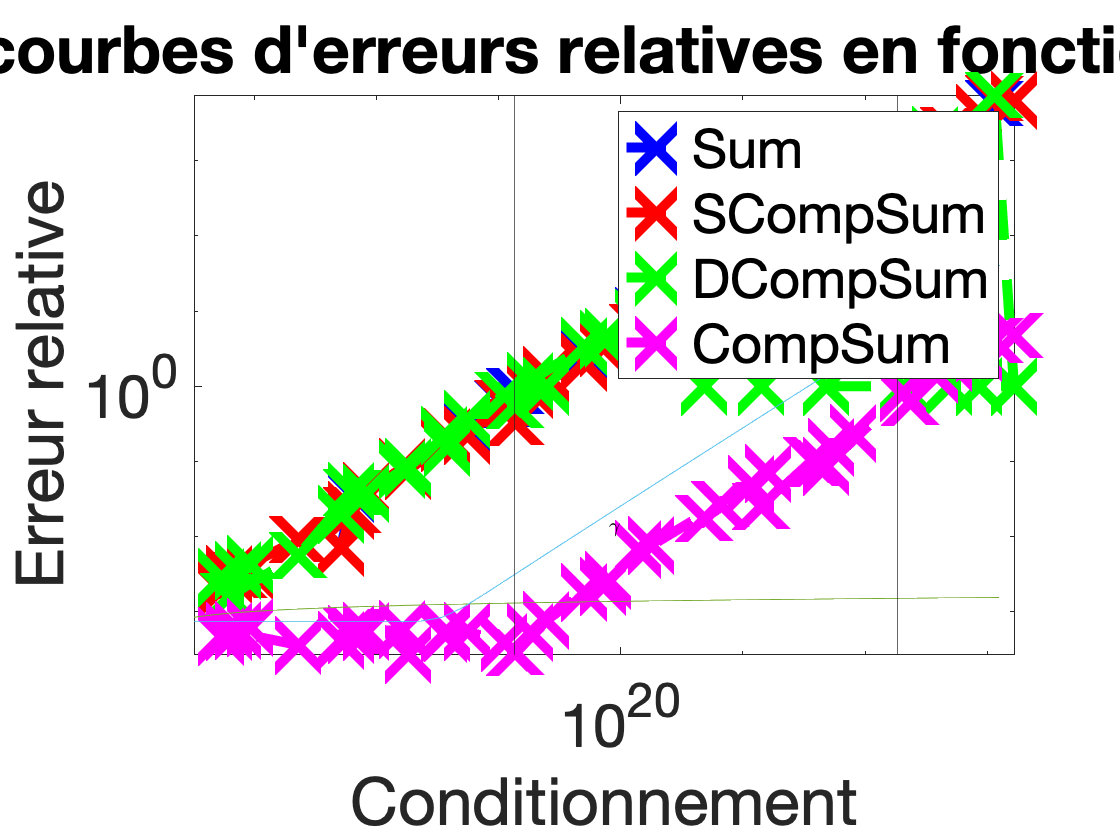

figure(2)
loglog(Ci,er5,'b--x')
hold on;
loglog(Ci,er6,'r--x')
hold on
loglog(Ci,er7,'g--x')
hold on
loglog(Ci,er8,'m--x')
hold on
xline(1/eps)
xline(1/(eps*eps))
hold on
loglog(c,cond3)
hold on;
loglog(c,cond4)
hold on;
t = text(Ci(20),cond4(20)+cond4(20)/4,'$\gamma$');
hold on
set(t,'Interpreter','latex');
legend('Sum','SCompSum','DCompSum','CompSum')
xlabel("Conditionnement")
ylabel("Erreur relative ")
title("Représentation des courbes d'erreurs relatives en fonction du conditionnement ")